# Machine Learning: Programming Exercise 5

## Regularized Linear Regression and Bias vs. Variance

In this exercise, you will implement regularized linear regression and use it to study models with different bias-variance properties.

### Files needed for this exercise

- `ex5.mlx` - MATLAB Live Script that steps you through the exercise

- `ex5data1.mat` - Dataset

- `submit.m` - Submission script that sends your solutions to our servers

- `featureNormalize.m` - Feature normalization function

- `fmincg.m` - Function minimization routine (similar to `fminunc`)

- `plotFit.m` - Plot a polynomial fit

- `trainLinearReg.m` - Trains linear regression using your cost function

- *`linearRegCostFunction.m` - Regularized linear regression cost function

- `*learningCurve.m` - Generates a learning curve

- *`polyFeatures.m` - Maps data into polynomial feature space

- *`validationCurve.m` - Generates a cross validation curve

****indicates files you will need to complete***

#### Confirm that your Current Folder is set correctly

Click into this section, then click the 'Run section' button above. This will execute the `dir` command below to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex5' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

dir

.                        ex5_companion.mlx        fmincg.m                 linearRegCostFunction.m  submit.m                 
..                       ex5data1.mat             learningCurve.m          plotFit.m                trainLinearReg.m         
ex5.mlx                  featureNormalize.m       lib                      polyFeatures.m           validationCurve.m        



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. Regularized Linear Regression

In the first half of the exercise, you will implement regularized linear regression to predict the amount of water flowing out of a dam using the change of water level in a reservoir. In the next half, you will go through some diagnostics of debugging learning algorithms and examine the effects of bias vs. variance.

### 1.1 Visualizing the dataset

We will begin by visualizing the dataset containing historical records on the change in the water level, $x$, and the amount of water flowing out of the dam, $y$. This dataset is divided into three parts:

- A **training** set that your model will learn on: `X, y`

- A **cross validation** set for determining the regularization parameter: `Xval, yval`

- A **test** set for evaluating performance. These are 'unseen' examples which your model did not see during training:` Xtest, ytest`

The code below will plot the training data (Figure 1). In the following parts, you will implement linear regression and use that to fit a straight line to the data and plot learning curves. Following that, you will implement polynomial regression to find a better fit to the data.

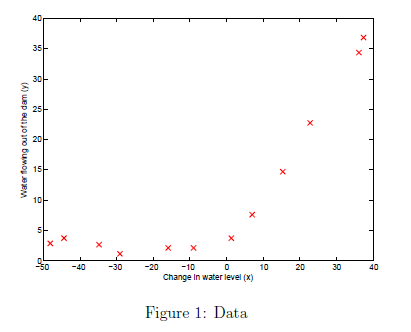

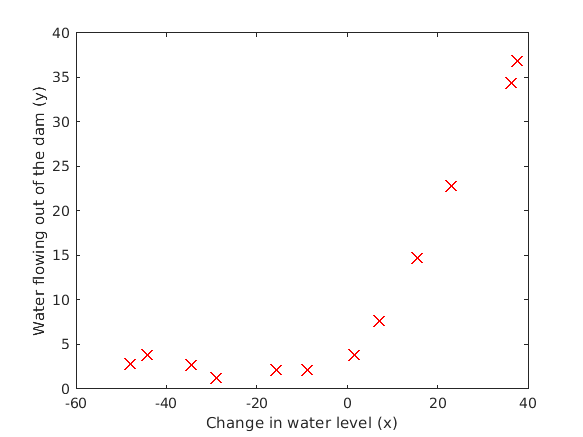

% Load from ex5data1: 
% You will have X, y, Xval, yval, Xtest, ytest in your environment
load ('ex5data1.mat');
% m = Number of examples
m = size(X, 1);

% Plot training data
figure;
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');

### 1.2 Regularized linear regression cost function

Recall that regularized linear regression has the following cost function:


$$J\left(\theta \right)=\frac{1}{2m}\left(\sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \right)+\frac{\;\lambda }{2m}\left(\sum_{j=1}^n \theta_j^2 \right)$$


where $\lambda$ is a regularization parameter which controls the degree of regularization (thus, helps preventing overtting). The regularization term puts a penalty on the overall cost $J$. As the magnitudes of the model parameters $\theta_j$ increase, the penalty increases as well. Note that you should not regularize the $\theta_0$ term. (In MATLAB, the $\theta_0$ term is represented as `theta(1)` since indexing in MATLAB starts from 1).

    You should now complete the code in the file `linearRegCostFunction.m`. Your task is to write a function to calculate the regularized linear regression cost function. If possible, try to vectorize your code and avoid writing loops. When you are finished, the code below will run your cost function using `theta` initialized at `[1; 1]`. You should expect to see an output of 303.993.

theta = [1 ; 1];
J = linearRegCostFunction([ones(m, 1) X], y, theta, 1);
fprintf('Cost at theta = [1 ; 1]: %f', J);

Cost at theta = [1 ; 1]: 303.993192

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 1.3 Regularized linear regression gradient

Correspondingly, the partial derivative of regularized linear regression's cost for $\theta_j$ is defined as


$$\begin{array}{l}
\frac{\partial J\left(\theta \right)}{\partial \theta_0 }=\frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \;\;\textrm{for}\;\;j=0\\
\frac{\partial J\left(\theta \right)}{\partial \theta_j }=\left(\frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \right)+\frac{\lambda }{m}\theta_j \;\;\;\textrm{for}\;\;j=0
\end{array}$$


In `linearRegCostFunction.m`, add code to calculate the gradient, returning it in the variable `grad`. When you are finished, the code below will run your gradient function using theta initialized at [1; 1]. You should expect to see a gradient of [-15.30; 598.250].

[J, grad] = linearRegCostFunction([ones(m, 1) X], y, theta, 1);
fprintf('Gradient at theta = [1 ; 1]:  [%f; %f] \n',grad(1), grad(2));

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 1.4 Fitting linear regression

Once your cost function and gradient are working correctly, the code in this section will run the code in `trainLinearReg.m` to compute the optimal values of $\theta$. This training function uses `fmincg` to optimize the cost function. In this part, we set regularization parameter $\lambda$ to zero. Because our current implementation of linear regression is trying to fit a 2-dimensional $\theta$, regularization will not be incredibly helpful for a $\theta$ of such low dimension. In the later parts of the exercise, you will be using polynomial regression with regularization.

%  Train linear regression with lambda = 0
lambda = 0;
[theta] = trainLinearReg([ones(m, 1) X], y, lambda);

Iteration     1 | Cost: 1.052435e+02
Iteration     2 | Cost: 2.237391e+01


    Finally, the code below should also plot the best fit line, resulting in an image similar to Figure 2. The best fit line tells us that the model is not a good fit to the data because the data has a nonlinear pattern. 

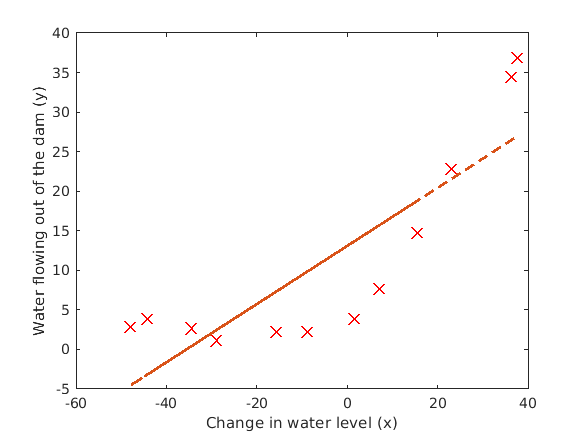

%  Plot fit over the data
figure;
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
hold on;
plot(X, [ones(m, 1) X]*theta, '--', 'LineWidth', 2)
hold off;

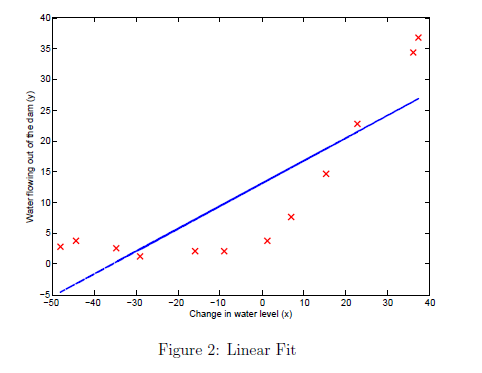

While visualizing the best fit as shown is one possible way to debug your learning algorithm, it is not always easy to visualize the data and model. In the next section, you will implement a function to generate learning curves that can help you debug your learning algorithm even if it is not easy to visualize the data.

## 2. Bias-variance

An important concept in machine learning is the bias-variance tradeoff. Models with high bias are not complex enough for the data and tend to underfit, while models with high variance overfit the training data. In this part of the exercise, you will plot training and test errors on a learning curve to diagnose bias-variance problems.

### 2.1 Learning curves

You will now implement code to generate the learning curves that will be useful in debugging learning algorithms. Recall that a learning curve plots training and cross validation error as a function of training set size. Your job is to fill in `learningCurve.m` so that it returns a vector of errors for the training set and cross validation set.

    To plot the learning curve, we need a training and cross validation set error for different training set sizes. To obtain different training set sizes, you should use different subsets of the original training set `X`. Specically, for a training set size of `i`, you should use the first `i` examples (i.e., `X(1:i,:) `and `y(1:i))`. You can use the `trainLinearReg` function to find the $\theta$ parameters. Note that `lambda` is passed as a parameter to the `learningCurve` function. After learning the $\theta$ parameters, you should compute the error on the training and cross validation sets. Recall that the training error for a dataset is defined as


$$J_{\textrm{train}} \left(\theta \right)=\frac{1}{2m}\left\lbrack \sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \right\rbrack$$


    In particular, note that the training error does not include the regularization term. One way to compute the training error is to use your existing cost function and set $\lambda$ to 0 only when using it to compute the training error and cross validation error. When you are computing the training set error, make sure you compute it on the training subset (i.e., `X(1:n,:)` and `y(1:n)`, instead of the entire training set). However, for the cross validation error, you should compute it over the entire cross validation set. You should store the computed errors in the vectors `error_train` and `error_val`.  

    In Figure 3, you can observe that both the train error and cross validation error are high when the number of training examples is increased. This reflects a high bias problem in the model - the linear regression model is too simple and is unable to fit our dataset well. In the next section, you will implement polynomial regression to fit a better model for this dataset.

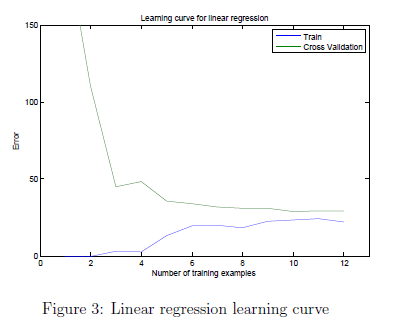

    When you are finished, run the code below to compute the learning curves and produce a plot similar to Figure 3.

lambda = 0;
[error_train, error_val] = learningCurve([ones(m, 1) X], y, [ones(size(Xval, 1), 1) Xval], yval, lambda);

Xtrain =     1.0000  -15.9368


ytrain = 2.1343

Iteration     1 | Cost: 3.628289e-04
Iteration     2 | Cost: 2.199486e-05
Iteration     3 | Cost: 4.157539e-09
Iteration     4 | Cost: 4.291129e-10
Iteration     5 | Cost: 1.297070e-11
Iteration     6 | Cost: 1.071136e-13
Iteration     7 | Cost: 1.418182e-15
Iteration     8 | Cost: 3.096638e-17
Iteration     9 | Cost: 6.236430e-18
Iteration    10 | Cost: 1.643627e-19
Iteration    11 | Cost: 1.515726e-21
Iteration    12 | Cost: 2.435846e-23
Iteration    13 | Cost: 4.257960e-25
Iteration    14 | Cost: 1.320908e-26
Iteration    15 | Cost: 2.666350e-28
Iteration    16 | Cost: 5.679799e-29
Iteration    17 | Cost: 2.465190e-30
Iteration    18 | Cost: 9.860761e-32
Iteration    19 | Cost: 0.000000e+00


theta =    -0.1429
   -0.1429


Xtrain =     1.0000  -15.9368
    1.0000  -29.1530


ytrain =     2.1343
    1.1733


Iteration     1 | Cost: 4.282328e-01
Iteration     2 | Cost: 8.332343e-30
Iteration     3 | Cost: 9.860761e-32


theta =     3.2932
    0.0727


Xtrain =     1.0000  -15.9368
    1.0000  -29.1530
    1.0000   36.1895


ytrain =     2.1343
    1.1733
   34.3591


Iteration     1 | Cost: 1.021540e+02
Iteration     2 | Cost: 3.286595e+00
Iteration     4 | Cost: 3.286595e+00
Iteration     5 | Cost: 3.286595e+00
Iteration     6 | Cost: 3.286595e+00
Iteration     7 | Cost: 3.286595e+00


theta =    14.1550
    0.5391


Xtrain =     1.0000  -15.9368
    1.0000  -29.1530
    1.0000   36.1895
    1.0000   37.4922


ytrain =     2.1343
    1.1733
   34.3591
   36.8380


Iteration     1 | Cost: 1.438726e+02
Iteration     2 | Cost: 1.035224e+02
Iteration     3 | Cost: 7.536716e+01
Iteration     4 | Cost: 1.615422e+01
Iteration     5 | Cost: 3.619255e+00
Iteration     6 | Cost: 3.013391e+00
Iteration     7 | Cost: 2.874590e+00
Iteration     8 | Cost: 2.843047e+00
Iteration     9 | Cost: 2.843029e+00
Iteration    10 | Cost: 2.843008e+00
Iteration    11 | Cost: 2.842993e+00
Iteration    12 | Cost: 2.842925e+00
Iteration    13 | Cost: 2.842865e+00
Iteration    14 | Cost: 2.842794e+00
Iteration    15 | Cost: 2.842715e+00
Iteration    16 | Cost: 2.842715e+00
Iteration    17 | Cost: 2.842710e+00
Iteration    18 | Cost: 2.842708e+00
Iteration    19 | Cost: 2.842706e+00
Iteration    20 | Cost: 2.842695e+00
Iteration    21 | Cost: 2.842683e+00
Iteration    22 | Cost: 2.842678e+00
Iteration    23 | Cost: 2.842678e+00
Iteration    24 | Cost: 2.842678e+00
Iteration    25 | Cost: 2.842678e+00
Iteration    26 | Cost: 2.842678e+00
Iteration    27 | Cost: 2.842678e+00
I

theta =    14.6243
    0.5599


Xtrain =     1.0000  -15.9368
    1.0000  -29.1530
    1.0000   36.1895
    1.0000   37.4922
    1.0000  -48.0588


ytrain =     2.1343
    1.1733
   34.3591
   36.8380
    2.8090


Iteration     1 | Cost: 1.592641e+02
Iteration     2 | Cost: 2.404966e+01
Iteration     3 | Cost: 2.354137e+01
Iteration     4 | Cost: 2.281160e+01
Iteration     5 | Cost: 2.276969e+01
Iteration     6 | Cost: 2.224060e+01
Iteration     7 | Cost: 1.920606e+01
Iteration     8 | Cost: 1.475292e+01
Iteration     9 | Cost: 1.430565e+01
Iteration    10 | Cost: 1.388881e+01
Iteration    11 | Cost: 1.327330e+01
Iteration    12 | Cost: 1.323519e+01
Iteration    13 | Cost: 1.319411e+01
Iteration    14 | Cost: 1.317355e+01
Iteration    15 | Cost: 1.315411e+01
Iteration    16 | Cost: 1.315405e+01
Iteration    17 | Cost: 1.315405e+01
Iteration    18 | Cost: 1.315405e+01
Iteration    19 | Cost: 1.315405e+01
Iteration    20 | Cost: 1.315405e+01
Iteration    21 | Cost: 1.315405e+01
Iteration    22 | Cost: 1.315405e+01
Iteration    23 | Cost: 1.315405e+01
Iteration    25 | Cost: 1.315405e+01


theta =    17.2138
    0.4497


Xtrain =     1.0000  -15.9368
    1.0000  -29.1530
    1.0000   36.1895
    1.0000   37.4922
    1.0000  -48.0588
    1.0000   -8.9415


ytrain =     2.1343
    1.1733
   34.3591
   36.8380
    2.8090
    2.1211


Iteration     1 | Cost: 1.531141e+02
Iteration     2 | Cost: 1.350947e+02
Iteration     3 | Cost: 1.137334e+02
Iteration     4 | Cost: 4.404199e+01
Iteration     5 | Cost: 2.957435e+01
Iteration     6 | Cost: 2.719561e+01
Iteration     7 | Cost: 1.949283e+01
Iteration     8 | Cost: 1.949128e+01
Iteration     9 | Cost: 1.945708e+01
Iteration    10 | Cost: 1.944472e+01
Iteration    11 | Cost: 1.944472e+01
Iteration    12 | Cost: 1.944471e+01
Iteration    13 | Cost: 1.944453e+01
Iteration    14 | Cost: 1.944425e+01
Iteration    15 | Cost: 1.944411e+01
Iteration    16 | Cost: 1.944396e+01
Iteration    17 | Cost: 1.944396e+01
Iteration    18 | Cost: 1.944396e+01
Iteration    19 | Cost: 1.944396e+01
Iteration    20 | Cost: 1.944396e+01
Iteration    21 | Cost: 1.944396e+01
Iteration    22 | Cost: 1.944396e+01
Iteration    23 | Cost: 1.944396e+01
Iteration    24 | Cost: 1.944396e+01
Iteration    25 | Cost: 1.944396e+01
Iteration    27 | Cost: 1.944396e+01
Iteration    28 | Cost: 1.944396e+01
I

theta =    15.4049
    0.4574


Xtrain =     1.0000  -15.9368
    1.0000  -29.1530
    1.0000   36.1895
    1.0000   37.4922
    1.0000  -48.0588
    1.0000   -8.9415
    1.0000   15.3078


ytrain =     2.1343
    1.1733
   34.3591
   36.8380
    2.8090
    2.1211
   14.7103


Iteration     1 | Cost: 1.383936e+02
Iteration     2 | Cost: 1.210275e+02
Iteration     3 | Cost: 1.013004e+02
Iteration     4 | Cost: 3.457729e+01
Iteration     5 | Cost: 2.808710e+01
Iteration     6 | Cost: 2.732288e+01
Iteration     7 | Cost: 2.011513e+01
Iteration     8 | Cost: 2.011508e+01
Iteration     9 | Cost: 2.010693e+01
Iteration    10 | Cost: 2.010640e+01
Iteration    11 | Cost: 2.010629e+01
Iteration    12 | Cost: 2.010382e+01
Iteration    13 | Cost: 2.009852e+01


theta =    14.2668
    0.4368


Xtrain =     1.0000  -15.9368
    1.0000  -29.1530
    1.0000   36.1895
    1.0000   37.4922
    1.0000  -48.0588
    1.0000   -8.9415
    1.0000   15.3078
    1.0000  -34.7063


ytrain =     2.1343
    1.1733
   34.3591
   36.8380
    2.8090
    2.1211
   14.7103
    2.6142


Iteration     1 | Cost: 1.237772e+02
Iteration     2 | Cost: 1.202532e+02
Iteration     3 | Cost: 1.195134e+02
Iteration     4 | Cost: 9.334231e+01
Iteration     5 | Cost: 4.813526e+01
Iteration     6 | Cost: 2.534679e+01
Iteration     7 | Cost: 1.817374e+01
Iteration     8 | Cost: 1.817286e+01
Iteration     9 | Cost: 1.817286e+01
Iteration    10 | Cost: 1.817286e+01
Iteration    11 | Cost: 1.817286e+01
Iteration    12 | Cost: 1.817286e+01
Iteration    13 | Cost: 1.817286e+01
Iteration    14 | Cost: 1.817286e+01
Iteration    15 | Cost: 1.817286e+01
Iteration    16 | Cost: 1.817286e+01
Iteration    17 | Cost: 1.817286e+01
Iteration    18 | Cost: 1.817286e+01
Iteration    19 | Cost: 1.817286e+01
Iteration    20 | Cost: 1.817286e+01
Iteration    22 | Cost: 1.817286e+01
Iteration    24 | Cost: 1.817286e+01
Iteration    25 | Cost: 1.817286e+01
Iteration    26 | Cost: 1.817286e+01
Iteration    28 | Cost: 1.817286e+01
Iteration    30 | Cost: 1.817286e+01


theta =    14.6234
    0.4231


Xtrain =     1.0000  -15.9368
    1.0000  -29.1530
    1.0000   36.1895
    1.0000   37.4922
    1.0000  -48.0588
    1.0000   -8.9415
    1.0000   15.3078
    1.0000  -34.7063
    1.0000    1.3892


ytrain =     2.1343
    1.1733
   34.3591
   36.8380
    2.8090
    2.1211
   14.7103
    2.6142
    3.7402


Iteration     1 | Cost: 1.089984e+02
Iteration     2 | Cost: 1.064701e+02
Iteration     3 | Cost: 1.054742e+02
Iteration     4 | Cost: 2.266786e+01
Iteration     5 | Cost: 2.266786e+01
Iteration     6 | Cost: 2.266758e+01
Iteration     7 | Cost: 2.260941e+01
Iteration     8 | Cost: 2.260941e+01
Iteration     9 | Cost: 2.260941e+01
Iteration    11 | Cost: 2.260941e+01


theta =    13.2966
    0.4130


Xtrain =     1.0000  -15.9368
    1.0000  -29.1530
    1.0000   36.1895
    1.0000   37.4922
    1.0000  -48.0588
    1.0000   -8.9415
    1.0000   15.3078
    1.0000  -34.7063
    1.0000    1.3892
    1.0000  -44.3838


ytrain =     2.1343
    1.1733
   34.3591
   36.8380
    2.8090
    2.1211
   14.7103
    2.6142
    3.7402
    3.7317


Iteration     1 | Cost: 1.108611e+02
Iteration     2 | Cost: 2.497543e+01
Iteration     3 | Cost: 2.496421e+01
Iteration     4 | Cost: 2.494838e+01
Iteration     5 | Cost: 2.493175e+01
Iteration     6 | Cost: 2.490656e+01
Iteration     7 | Cost: 2.474473e+01
Iteration     8 | Cost: 2.326195e+01
Iteration     9 | Cost: 2.326195e+01
Iteration    10 | Cost: 2.326187e+01
Iteration    11 | Cost: 2.326187e+01
Iteration    12 | Cost: 2.326186e+01
Iteration    13 | Cost: 2.326186e+01
Iteration    14 | Cost: 2.326181e+01
Iteration    15 | Cost: 2.326147e+01
Iteration    16 | Cost: 2.326146e+01
Iteration    17 | Cost: 2.326146e+01


theta =    13.8537
    0.3778


Xtrain =     1.0000  -15.9368
    1.0000  -29.1530
    1.0000   36.1895
    1.0000   37.4922
    1.0000  -48.0588
    1.0000   -8.9415
    1.0000   15.3078
    1.0000  -34.7063
    1.0000    1.3892
    1.0000  -44.3838


ytrain =     2.1343
    1.1733
   34.3591
   36.8380
    2.8090
    2.1211
   14.7103
    2.6142
    3.7402
    3.7317


Iteration     1 | Cost: 1.023394e+02
Iteration     2 | Cost: 2.443039e+01
Iteration     3 | Cost: 2.443033e+01
Iteration     4 | Cost: 2.442972e+01
Iteration     5 | Cost: 2.441042e+01
Iteration     6 | Cost: 2.435852e+01
Iteration     7 | Cost: 2.431735e+01
Iteration     8 | Cost: 2.431733e+01
Iteration     9 | Cost: 2.431727e+01
Iteration    10 | Cost: 2.431725e+01


theta =    12.9372
    0.3634


Xtrain =     1.0000  -15.9368
    1.0000  -29.1530
    1.0000   36.1895
    1.0000   37.4922
    1.0000  -48.0588
    1.0000   -8.9415
    1.0000   15.3078
    1.0000  -34.7063
    1.0000    1.3892
    1.0000  -44.3838


ytrain =     2.1343
    1.1733
   34.3591
   36.8380
    2.8090
    2.1211
   14.7103
    2.6142
    3.7402
    3.7317


Iteration     1 | Cost: 1.052435e+02
Iteration     2 | Cost: 2.237391e+01


theta =    13.0879
    0.3678


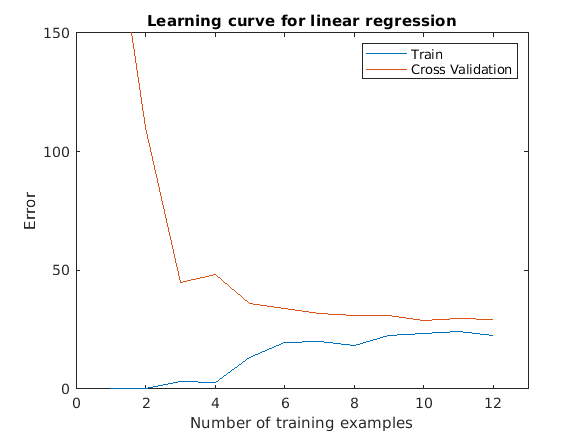


plot(1:m, error_train, 1:m, error_val);
title('Learning curve for linear regression')
legend('Train', 'Cross Validation')
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 150])


fprintf('# Training Examples\tTrain Error\tCross Validation Error\n');

# Training Examples	Train Error	Cross Validation Error


for i = 1:m
    fprintf('  \t%d\t\t%f\t%f\n', i, error_train(i), error_val(i));
end

  	1		0.000000	210.522449
  	2		0.000000	110.300366
  	3		3.286595	45.010231
  	4		2.842678	48.368911
  	5		13.154049	35.865165
  	6		19.443963	33.829962
  	7		20.098522	31.970986
  	8		18.172859	30.862446
  	9		22.609405	31.135998
  	10		23.261462	28.936207
  	11		24.317250	29.551432
  	12		22.373906	29.433818


## 3. Polynomial regression

The problem with our linear model was that it was too simple for the data and resulted in underfitting (high bias). In this part of the exercise, you will address this problem by adding more features. For use polynomial regression, our hypothesis has the form:


$$h_\theta(x) =\theta_0+\theta_1\ast (waterLevel)+\theta_2*
(waterLevel)^2+\cdots+\theta_p\ast (waterLevel)^p \\
\qquad\;=\theta_0+\theta_1 x_1+\theta_2 x_2+\cdots+\theta_p x_p \end{aligned}$$


Notice that by defining $x_1 = (\text{waterLevel}), x_2 = (\text{waterLevel)}^2,\ldots,x_p = (\text{waterLevel})^p$, we obtain a linear regression model where the features are the various powers of the original value (*waterLevel*).

    Now, you will add more features using the higher powers of the existing feature $x$ in the dataset. Your task in this part is to complete the code in `polyFeatures.`m so that the function maps the original training set `X` of size $m\times 1$into its higher powers. Specifically, when a training set $X$ of size $m\times 1$ is passed into the function, the function should return a $m\times p$ matrix `X_poly`, where column 1 holds the original values of `X`, column 2 holds the values of `X.^2`, column 3 holds the values of `X.^3`, and so on. Note that you don't have to account for the zero-th power in this function. Now that you have a function that will map features to a higher dimension, the code in the next section will apply it to the training set, the test set, and the cross validation set (which you haven't used yet).

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 3.1 Learning Polynomial Regression

After you have completed `polyFeatures.m`, run the code below to train polynomial regression using your linear regression cost function. Keep in mind that even though we have polynomial terms in our feature vector, we are still solving a linear regression optimization problem. The polynomial terms have simply turned into features that we can use for linear regression. We are using the same cost function and gradient that you wrote for the earlier part of this exercise.

    For this part of the exercise, you will be using a polynomial of degree 8. It turns out that if we run the training directly on the projected data, it will not work well as the features would be badly scaled (e.g., an example with $x = 40$ will now have a feature $x_8 = 40^8 = 6:5\times 10^{12$) Therefore, you will need to use feature normalization. Before learning the parameters $\theta$ for the polynomial regression, code in below will first call `featureNormalize` to normalize the features of the training set, storing the `mu`, `sigma` parameters separately. We have already implemented this function for you and it is the same function from the first exercise.

p = 8;

% Map X onto Polynomial Features and Normalize
X_poly = polyFeatures(X, p);
[X_poly, mu, sigma] = featureNormalize(X_poly);  % Normalize
X_poly = [ones(m, 1), X_poly];                   % Add Ones

% % Map X_poly_test and normalize (using mu and sigma)
X_poly_test = polyFeatures(Xtest, p);
X_poly_test = X_poly_test-mu; % uses implicit expansion instead of bsxfun
X_poly_test = X_poly_test./sigma; % uses implicit expansion instead of bsxfun
X_poly_test = [ones(size(X_poly_test, 1), 1), X_poly_test];         % Add Ones

% Map X_poly_val and normalize (using mu and sigma)
X_poly_val = polyFeatures(Xval, p);
X_poly_val = X_poly_val-mu; % uses implicit expansion instead of bsxfun
X_poly_val = X_poly_val./sigma; % uses implicit expansion instead of bsxfun
X_poly_val = [ones(size(X_poly_val, 1), 1), X_poly_val];           % Add Ones

fprintf('Normalized Training Example 1:\n');

Normalized Training Example 1:


fprintf('  %f  \n', X_poly(1, :));

  1.000000  
  -0.362141  
  -0.755087  
  0.182226  
  -0.706190  
  0.306618  
  -0.590878  
  0.344516  
  -0.508481  



lambda = 0;
[theta] = trainLinearReg(X_poly, y, lambda);

Iteration     1 | Cost: 8.273077e+01
Iteration     2 | Cost: 2.687496e+01
Iteration     3 | Cost: 1.327780e+01
Iteration     4 | Cost: 3.455324e+00
Iteration     5 | Cost: 2.870493e+00
Iteration     6 | Cost: 2.404364e+00
Iteration     7 | Cost: 2.372779e+00
Iteration     8 | Cost: 1.771555e+00
Iteration     9 | Cost: 1.210317e+00
Iteration    10 | Cost: 9.416385e-01
Iteration    11 | Cost: 7.336614e-01
Iteration    12 | Cost: 6.496678e-01
Iteration    13 | Cost: 5.709121e-01
Iteration    14 | Cost: 4.968226e-01
Iteration    15 | Cost: 4.770904e-01
Iteration    16 | Cost: 4.720070e-01
Iteration    17 | Cost: 4.560603e-01
Iteration    18 | Cost: 4.538448e-01
Iteration    19 | Cost: 4.333054e-01
Iteration    20 | Cost: 4.090062e-01
Iteration    21 | Cost: 3.879862e-01
Iteration    22 | Cost: 3.714376e-01
Iteration    23 | Cost: 3.522901e-01
Iteration    24 | Cost: 3.477121e-01
Iteration    25 | Cost: 3.432612e-01
Iteration    26 | Cost: 3.415146e-01
Iteration    27 | Cost: 3.298495e-01
I

    After learning the parameters $\theta$, the code below will generate two plots (Figures 4,5) for polynomial regression with $\lambda = 0$. 

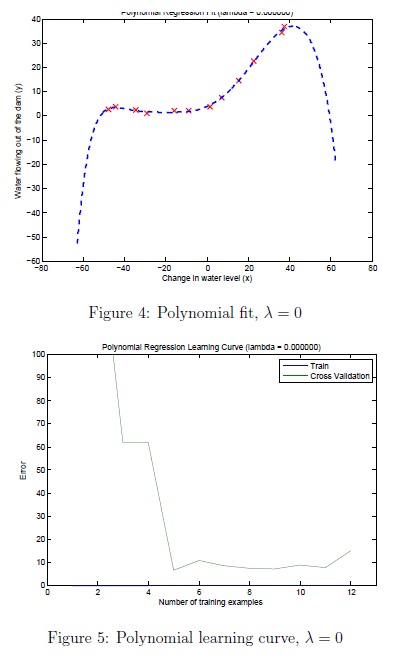

From Figure 4, you should see that the polynomial fit is able to follow the datapoints very well - thus, obtaining a low training error. However, the polynomial fit is very complex and even drops off at the extremes. This is an indicator that the polynomial regression model is overfitting the training data and will not generalize well.

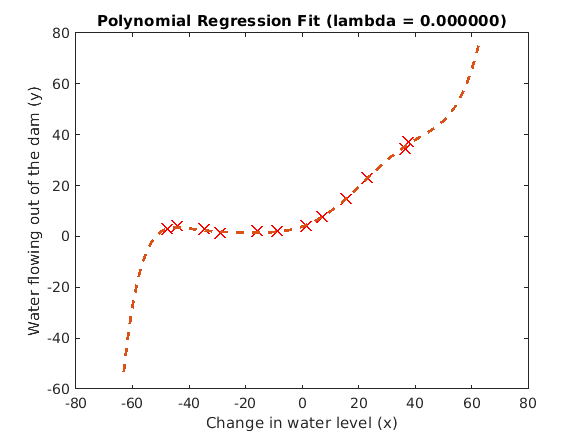

% Plot training data and fit
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
plotFit(min(X), max(X), mu, sigma, theta, p);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
title (sprintf('Polynomial Regression Fit (lambda = %f)', lambda));

[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);

Xtrain =     1.0000   -0.3621   -0.7551    0.1822   -0.7062    0.3066   -0.5909    0.3445   -0.5085


ytrain = 2.1343

Iteration     1 | Cost: 2.865325e-01
Iteration     2 | Cost: 1.896079e-03
Iteration     3 | Cost: 5.614798e-08
Iteration     4 | Cost: 6.250433e-09
Iteration     5 | Cost: 1.771778e-10
Iteration     6 | Cost: 5.404078e-12
Iteration     7 | Cost: 3.142740e-13
Iteration     8 | Cost: 2.182675e-15
Iteration     9 | Cost: 2.113504e-16
Iteration    10 | Cost: 2.257216e-18
Iteration    11 | Cost: 2.888868e-19
Iteration    12 | Cost: 1.569615e-20
Iteration    13 | Cost: 1.041735e-22
Iteration    14 | Cost: 6.923008e-24
Iteration    15 | Cost: 1.416410e-26
Iteration    16 | Cost: 1.692205e-27
Iteration    17 | Cost: 7.730837e-29
Iteration    18 | Cost: 9.860761e-32
Iteration    19 | Cost: 0.000000e+00


theta =    -1.9591
   -1.9591
   -1.9591
   -1.9591
   -1.9591
   -1.9591
   -1.9591
   -1.9591
   -1.9591


Xtrain =     1.0000   -0.3621   -0.7551    0.1822   -0.7062    0.3066   -0.5909    0.3445   -0.5085
    1.0000   -0.8032    0.0013   -0.2479   -0.3270    0.0934   -0.4358    0.2554   -0.4489


ytrain =     2.1343
    1.1733


Iteration     1 | Cost: 5.373343e-02
Iteration     2 | Cost: 2.656989e-04
Iteration     3 | Cost: 1.480972e-05
Iteration     4 | Cost: 1.420517e-11
Iteration     5 | Cost: 7.255780e-12
Iteration     6 | Cost: 1.293770e-14
Iteration     7 | Cost: 1.291564e-14
Iteration     8 | Cost: 6.787523e-15
Iteration     9 | Cost: 4.423133e-16
Iteration    10 | Cost: 2.255088e-16
Iteration    11 | Cost: 1.041959e-18
Iteration    12 | Cost: 2.733926e-19
Iteration    13 | Cost: 3.946247e-21
Iteration    14 | Cost: 6.162976e-32
Iteration    15 | Cost: 0.000000e+00


theta =     0.5958
   -0.0733
   -0.6941
    0.2475
   -0.5432
    0.2515
   -0.4021
    0.2340
   -0.3222


Xtrain =     1.0000   -0.3621   -0.7551    0.1822   -0.7062    0.3066   -0.5909    0.3445   -0.5085
    1.0000   -0.8032    0.0013   -0.2479   -0.3270    0.0934   -0.4358    0.2554   -0.4489
    1.0000    1.3775    0.5848    1.2498    0.2453    0.9784   -0.0122    0.7566   -0.1704


ytrain =     2.1343
    1.1733
   34.3591


Iteration     1 | Cost: 3.023381e+01
Iteration     2 | Cost: 9.745401e-01
Iteration     3 | Cost: 4.827305e-01
Iteration     4 | Cost: 1.170249e-02
Iteration     5 | Cost: 9.696908e-04
Iteration     6 | Cost: 5.299258e-04
Iteration     7 | Cost: 1.985836e-04
Iteration     8 | Cost: 6.032119e-05
Iteration     9 | Cost: 6.225212e-07
Iteration    10 | Cost: 3.894758e-07
Iteration    11 | Cost: 7.703724e-08
Iteration    12 | Cost: 5.688321e-08
Iteration    13 | Cost: 5.385450e-09
Iteration    14 | Cost: 1.603656e-10
Iteration    15 | Cost: 1.516867e-11
Iteration    16 | Cost: 9.627464e-12
Iteration    17 | Cost: 2.794098e-12
Iteration    18 | Cost: 7.766256e-13
Iteration    19 | Cost: 1.571268e-13
Iteration    20 | Cost: 2.248293e-16
Iteration    21 | Cost: 5.079311e-17
Iteration    22 | Cost: 1.499570e-17
Iteration    23 | Cost: 3.850966e-18
Iteration    24 | Cost: 4.272997e-31
Iteration    25 | Cost: 3.286920e-32


theta =     6.3942
    6.0725
    6.1249
    5.6590
    2.6152
    5.0238
    0.2492
    4.2528
   -1.0254


Xtrain =     1.0000   -0.3621   -0.7551    0.1822   -0.7062    0.3066   -0.5909    0.3445   -0.5085
    1.0000   -0.8032    0.0013   -0.2479   -0.3270    0.0934   -0.4358    0.2554   -0.4489
    1.0000    1.3775    0.5848    1.2498    0.2453    0.9784   -0.0122    0.7566   -0.1704
    1.0000    1.4209    0.7066    1.3598    0.3955    1.1062    0.1256    0.8719   -0.0596


ytrain =     2.1343
    1.1733
   34.3591
   36.8380


Iteration     1 | Cost: 7.960488e-01
Iteration     2 | Cost: 2.114171e-01
Iteration     3 | Cost: 2.702642e-02
Iteration     4 | Cost: 3.974902e-19
Iteration     5 | Cost: 2.076487e-25
Iteration     6 | Cost: 6.198756e-26
Iteration     7 | Cost: 2.266823e-27
Iteration     8 | Cost: 4.587719e-28


theta =     6.5574
    7.5559
    6.9020
    5.1406
    1.9603
    3.8532
   -0.9940
    3.0128
   -2.2925


Xtrain =     1.0000   -0.3621   -0.7551    0.1822   -0.7062    0.3066   -0.5909    0.3445   -0.5085
    1.0000   -0.8032    0.0013   -0.2479   -0.3270    0.0934   -0.4358    0.2554   -0.4489
    1.0000    1.3775    0.5848    1.2498    0.2453    0.9784   -0.0122    0.7566   -0.1704
    1.0000    1.4209    0.7066    1.3598    0.3955    1.1062    0.1256    0.8719   -0.0596
    1.0000   -1.4341    1.8540   -2.0372    2.3314   -2.4115    2.6022   -2.6457    2.7661


ytrain =     2.1343
    1.1733
   34.3591
   36.8380
    2.8090


Iteration     1 | Cost: 9.143237e+01
Iteration     2 | Cost: 2.762462e+01
Iteration     3 | Cost: 3.042180e+00
Iteration     4 | Cost: 1.459599e+00
Iteration     5 | Cost: 1.188529e-01
Iteration     6 | Cost: 9.480159e-02
Iteration     7 | Cost: 8.115905e-02
Iteration     8 | Cost: 7.457730e-02
Iteration     9 | Cost: 6.721783e-02
Iteration    10 | Cost: 6.204212e-02
Iteration    11 | Cost: 6.031427e-02
Iteration    12 | Cost: 5.834369e-02
Iteration    13 | Cost: 5.285739e-02
Iteration    14 | Cost: 5.151427e-02
Iteration    15 | Cost: 4.850000e-02
Iteration    16 | Cost: 4.093029e-02
Iteration    17 | Cost: 3.123312e-02
Iteration    18 | Cost: 3.076337e-02
Iteration    19 | Cost: 2.996092e-02
Iteration    20 | Cost: 2.955500e-02
Iteration    21 | Cost: 2.918820e-02
Iteration    22 | Cost: 2.905909e-02
Iteration    23 | Cost: 2.886845e-02
Iteration    24 | Cost: 2.736191e-02
Iteration    25 | Cost: 2.690724e-02
Iteration    26 | Cost: 2.626477e-02
Iteration    27 | Cost: 2.562913e-02
I

theta =    10.4189
    8.3498
    5.5797
    5.1720
    2.6391
    2.0788
    1.0129
    0.1531
    0.4287


Xtrain =     1.0000   -0.3621   -0.7551    0.1822   -0.7062    0.3066   -0.5909    0.3445   -0.5085
    1.0000   -0.8032    0.0013   -0.2479   -0.3270    0.0934   -0.4358    0.2554   -0.4489
    1.0000    1.3775    0.5848    1.2498    0.2453    0.9784   -0.0122    0.7566   -0.1704
    1.0000    1.4209    0.7066    1.3598    0.3955    1.1062    0.1256    0.8719   -0.0596
    1.0000   -1.4341    1.8540   -2.0372    2.3314   -2.4115    2.6022   -2.6457    2.7661
    1.0000   -0.1287   -0.9760    0.2514   -0.7397    0.3170   -0.5950    0.3458   -0.5090


ytrain =     2.1343
    1.1733
   34.3591
   36.8380
    2.8090
    2.1211


Iteration     1 | Cost: 6.685771e+01
Iteration     2 | Cost: 1.216701e+01
Iteration     3 | Cost: 1.795979e+00
Iteration     4 | Cost: 6.292963e-01
Iteration     5 | Cost: 2.225698e-01
Iteration     6 | Cost: 5.075312e-02
Iteration     7 | Cost: 4.971823e-02
Iteration     8 | Cost: 4.887208e-02
Iteration     9 | Cost: 4.848291e-02
Iteration    10 | Cost: 4.805697e-02
Iteration    11 | Cost: 4.762059e-02
Iteration    12 | Cost: 4.708462e-02
Iteration    13 | Cost: 4.655857e-02
Iteration    14 | Cost: 4.628947e-02
Iteration    15 | Cost: 4.627246e-02
Iteration    16 | Cost: 4.607441e-02
Iteration    17 | Cost: 4.587981e-02
Iteration    18 | Cost: 4.577667e-02
Iteration    19 | Cost: 4.559270e-02
Iteration    20 | Cost: 4.541106e-02
Iteration    21 | Cost: 4.519288e-02
Iteration    22 | Cost: 4.510660e-02
Iteration    23 | Cost: 4.486349e-02
Iteration    24 | Cost: 4.391140e-02
Iteration    25 | Cost: 4.289110e-02
Iteration    26 | Cost: 3.971951e-02
Iteration    27 | Cost: 3.853581e-02
I

theta =     9.3430
    5.2067
    8.8464
   10.6861
   -1.6355
    2.8932
    0.3383
   -3.5886
    2.4290


Xtrain =     1.0000   -0.3621   -0.7551    0.1822   -0.7062    0.3066   -0.5909    0.3445   -0.5085
    1.0000   -0.8032    0.0013   -0.2479   -0.3270    0.0934   -0.4358    0.2554   -0.4489
    1.0000    1.3775    0.5848    1.2498    0.2453    0.9784   -0.0122    0.7566   -0.1704
    1.0000    1.4209    0.7066    1.3598    0.3955    1.1062    0.1256    0.8719   -0.0596
    1.0000   -1.4341    1.8540   -2.0372    2.3314   -2.4115    2.6022   -2.6457    2.7661
    1.0000   -0.1287   -0.9760    0.2514   -0.7397    0.3170   -0.5950    0.3458   -0.5090
    1.0000    0.6806   -0.7800    0.3407   -0.7117    0.3265   -0.5918    0.3468   -0.5086


ytrain =     2.1343
    1.1733
   34.3591
   36.8380
    2.8090
    2.1211
   14.7103


Iteration     1 | Cost: 7.107198e+01
Iteration     2 | Cost: 7.654021e+00
Iteration     3 | Cost: 7.401261e+00
Iteration     4 | Cost: 4.177906e+00
Iteration     5 | Cost: 1.700425e+00
Iteration     6 | Cost: 1.419801e+00
Iteration     7 | Cost: 1.225070e+00
Iteration     8 | Cost: 1.120144e+00
Iteration     9 | Cost: 9.856425e-01
Iteration    10 | Cost: 8.482548e-01
Iteration    11 | Cost: 7.930359e-01
Iteration    12 | Cost: 7.915596e-01
Iteration    13 | Cost: 7.432637e-01
Iteration    14 | Cost: 6.905931e-01
Iteration    15 | Cost: 6.711417e-01
Iteration    16 | Cost: 4.571961e-01
Iteration    17 | Cost: 3.811756e-01
Iteration    18 | Cost: 3.254092e-01
Iteration    19 | Cost: 3.093322e-01
Iteration    20 | Cost: 2.445255e-01
Iteration    21 | Cost: 2.245541e-01
Iteration    22 | Cost: 1.955669e-01
Iteration    23 | Cost: 1.906655e-01
Iteration    24 | Cost: 1.838569e-01
Iteration    25 | Cost: 1.806344e-01
Iteration    26 | Cost: 1.685436e-01
Iteration    27 | Cost: 1.654675e-01
I

theta =    10.2594
   12.7411
   16.2755
   -3.6880
  -23.3443
    6.8646
    2.7499
    5.0001
   18.1431


Xtrain =     1.0000   -0.3621   -0.7551    0.1822   -0.7062    0.3066   -0.5909    0.3445   -0.5085
    1.0000   -0.8032    0.0013   -0.2479   -0.3270    0.0934   -0.4358    0.2554   -0.4489
    1.0000    1.3775    0.5848    1.2498    0.2453    0.9784   -0.0122    0.7566   -0.1704
    1.0000    1.4209    0.7066    1.3598    0.3955    1.1062    0.1256    0.8719   -0.0596
    1.0000   -1.4341    1.8540   -2.0372    2.3314   -2.4115    2.6022   -2.6457    2.7661
    1.0000   -0.1287   -0.9760    0.2514   -0.7397    0.3170   -0.5950    0.3458   -0.5090
    1.0000    0.6806   -0.7800    0.3407   -0.7117    0.3265   -0.5918    0.3468   -0.5086
    1.0000   -0.9885    0.4514   -0.6013    0.0929   -0.2185   -0.1416    0.0394   -0.2667


ytrain =     2.1343
    1.1733
   34.3591
   36.8380
    2.8090
    2.1211
   14.7103
    2.6142


Iteration     1 | Cost: 6.233475e+01
Iteration     2 | Cost: 5.909133e+00
Iteration     3 | Cost: 5.312532e+00
Iteration     4 | Cost: 2.796332e+00
Iteration     5 | Cost: 2.007671e+00
Iteration     6 | Cost: 1.374072e+00
Iteration     7 | Cost: 1.338201e+00
Iteration     8 | Cost: 1.184754e+00
Iteration     9 | Cost: 1.136363e+00
Iteration    10 | Cost: 9.960309e-01
Iteration    11 | Cost: 8.431097e-01
Iteration    12 | Cost: 7.146556e-01
Iteration    13 | Cost: 6.419279e-01
Iteration    14 | Cost: 4.783781e-01
Iteration    15 | Cost: 3.858842e-01
Iteration    16 | Cost: 3.831411e-01
Iteration    17 | Cost: 3.490458e-01
Iteration    18 | Cost: 3.162566e-01
Iteration    19 | Cost: 3.088518e-01
Iteration    20 | Cost: 2.757939e-01
Iteration    21 | Cost: 2.493796e-01
Iteration    22 | Cost: 2.184280e-01
Iteration    23 | Cost: 1.729548e-01
Iteration    24 | Cost: 1.546415e-01
Iteration    25 | Cost: 1.428622e-01
Iteration    26 | Cost: 1.281659e-01
Iteration    27 | Cost: 1.234545e-01
I

theta =    11.3396
   13.0591
    7.6435
   -1.8411
   -1.2289
    0.6472
    1.7286
    3.9383
    0.9522


Xtrain =     1.0000   -0.3621   -0.7551    0.1822   -0.7062    0.3066   -0.5909    0.3445   -0.5085
    1.0000   -0.8032    0.0013   -0.2479   -0.3270    0.0934   -0.4358    0.2554   -0.4489
    1.0000    1.3775    0.5848    1.2498    0.2453    0.9784   -0.0122    0.7566   -0.1704
    1.0000    1.4209    0.7066    1.3598    0.3955    1.1062    0.1256    0.8719   -0.0596
    1.0000   -1.4341    1.8540   -2.0372    2.3314   -2.4115    2.6022   -2.6457    2.7661
    1.0000   -0.1287   -0.9760    0.2514   -0.7397    0.3170   -0.5950    0.3458   -0.5090
    1.0000    0.6806   -0.7800    0.3407   -0.7117    0.3265   -0.5918    0.3468   -0.5086
    1.0000   -0.9885    0.4514   -0.6013    0.0929   -0.2185   -0.1416    0.0394   -0.2667
    1.0000    0.2161   -1.0750    0.2663   -0.7434    0.3176   -0.5951    0.3458   -0.5090


ytrain =     2.1343
    1.1733
   34.3591
   36.8380
    2.8090
    2.1211
   14.7103
    2.6142
    3.7402


Iteration     1 | Cost: 5.922449e+01
Iteration     2 | Cost: 2.724806e+00
Iteration     3 | Cost: 1.507147e+00
Iteration     4 | Cost: 1.432125e+00
Iteration     5 | Cost: 1.346524e+00
Iteration     6 | Cost: 1.194506e+00
Iteration     7 | Cost: 1.101745e+00
Iteration     8 | Cost: 1.034253e+00
Iteration     9 | Cost: 8.941222e-01
Iteration    10 | Cost: 7.078956e-01
Iteration    11 | Cost: 6.936487e-01
Iteration    12 | Cost: 6.307029e-01
Iteration    13 | Cost: 6.066634e-01
Iteration    14 | Cost: 6.043825e-01
Iteration    15 | Cost: 5.604546e-01
Iteration    16 | Cost: 5.117711e-01
Iteration    17 | Cost: 4.571271e-01
Iteration    18 | Cost: 4.467624e-01
Iteration    19 | Cost: 4.011434e-01
Iteration    20 | Cost: 3.664743e-01
Iteration    21 | Cost: 3.462707e-01
Iteration    22 | Cost: 3.449405e-01
Iteration    23 | Cost: 3.355352e-01
Iteration    24 | Cost: 3.337504e-01
Iteration    25 | Cost: 3.297668e-01
Iteration    26 | Cost: 3.274827e-01
Iteration    27 | Cost: 3.271931e-01
I

theta =    10.9747
   11.7789
   15.5075
    5.5077
  -17.2378
   -9.9948
    8.4066
    8.3104
    2.6876


Xtrain =     1.0000   -0.3621   -0.7551    0.1822   -0.7062    0.3066   -0.5909    0.3445   -0.5085
    1.0000   -0.8032    0.0013   -0.2479   -0.3270    0.0934   -0.4358    0.2554   -0.4489
    1.0000    1.3775    0.5848    1.2498    0.2453    0.9784   -0.0122    0.7566   -0.1704
    1.0000    1.4209    0.7066    1.3598    0.3955    1.1062    0.1256    0.8719   -0.0596
    1.0000   -1.4341    1.8540   -2.0372    2.3314   -2.4115    2.6022   -2.6457    2.7661
    1.0000   -0.1287   -0.9760    0.2514   -0.7397    0.3170   -0.5950    0.3458   -0.5090
    1.0000    0.6806   -0.7800    0.3407   -0.7117    0.3265   -0.5918    0.3468   -0.5086
    1.0000   -0.9885    0.4514   -0.6013    0.0929   -0.2185   -0.1416    0.0394   -0.2667
    1.0000    0.2161   -1.0750    0.2663   -0.7434    0.3176   -0.5951    0.3458   -0.5090
    1.0000   -1.3115    1.4228   -1.5481    1.4934   -1.5159    1.3887   -1.3683    1.2241


ytrain =     2.1343
    1.1733
   34.3591
   36.8380
    2.8090
    2.1211
   14.7103
    2.6142
    3.7402
    3.7317


Iteration     1 | Cost: 5.599132e+01
Iteration     2 | Cost: 1.160850e+01
Iteration     3 | Cost: 5.777511e+00
Iteration     4 | Cost: 3.138721e+00
Iteration     5 | Cost: 1.743808e+00
Iteration     6 | Cost: 1.324477e+00
Iteration     7 | Cost: 1.115175e+00
Iteration     8 | Cost: 8.331651e-01
Iteration     9 | Cost: 7.154457e-01
Iteration    10 | Cost: 6.490978e-01
Iteration    11 | Cost: 6.421023e-01
Iteration    12 | Cost: 4.399753e-01
Iteration    13 | Cost: 3.555978e-01
Iteration    14 | Cost: 3.334997e-01
Iteration    15 | Cost: 3.283517e-01
Iteration    16 | Cost: 3.269075e-01
Iteration    17 | Cost: 3.219600e-01
Iteration    18 | Cost: 3.217646e-01
Iteration    19 | Cost: 3.197461e-01
Iteration    20 | Cost: 3.182527e-01
Iteration    21 | Cost: 3.114568e-01
Iteration    22 | Cost: 3.040777e-01
Iteration    23 | Cost: 3.038746e-01
Iteration    24 | Cost: 3.030345e-01
Iteration    25 | Cost: 3.021990e-01
Iteration    26 | Cost: 3.017300e-01
Iteration    27 | Cost: 3.015898e-01
I

theta =    11.1132
   11.6302
   12.9364
    6.6786
   -9.7924
   -8.7421
    6.9014
    3.2977
   -3.3798


Xtrain =     1.0000   -0.3621   -0.7551    0.1822   -0.7062    0.3066   -0.5909    0.3445   -0.5085
    1.0000   -0.8032    0.0013   -0.2479   -0.3270    0.0934   -0.4358    0.2554   -0.4489
    1.0000    1.3775    0.5848    1.2498    0.2453    0.9784   -0.0122    0.7566   -0.1704
    1.0000    1.4209    0.7066    1.3598    0.3955    1.1062    0.1256    0.8719   -0.0596
    1.0000   -1.4341    1.8540   -2.0372    2.3314   -2.4115    2.6022   -2.6457    2.7661
    1.0000   -0.1287   -0.9760    0.2514   -0.7397    0.3170   -0.5950    0.3458   -0.5090
    1.0000    0.6806   -0.7800    0.3407   -0.7117    0.3265   -0.5918    0.3468   -0.5086
    1.0000   -0.9885    0.4514   -0.6013    0.0929   -0.2185   -0.1416    0.0394   -0.2667
    1.0000    0.2161   -1.0750    0.2663   -0.7434    0.3176   -0.5951    0.3458   -0.5090
    1.0000   -1.3115    1.4228   -1.5481    1.4934   -1.5159    1.3887   -1.3683    1.2241


ytrain =     2.1343
    1.1733
   34.3591
   36.8380
    2.8090
    2.1211
   14.7103
    2.6142
    3.7402
    3.7317


Iteration     1 | Cost: 7.186879e+01
Iteration     2 | Cost: 2.278130e+01
Iteration     3 | Cost: 4.970159e+00
Iteration     4 | Cost: 1.355413e+00
Iteration     5 | Cost: 1.252814e+00
Iteration     6 | Cost: 1.187923e+00
Iteration     7 | Cost: 1.157952e+00
Iteration     8 | Cost: 1.037921e+00
Iteration     9 | Cost: 9.148964e-01
Iteration    10 | Cost: 8.955767e-01
Iteration    11 | Cost: 8.324073e-01
Iteration    12 | Cost: 7.618097e-01
Iteration    13 | Cost: 6.268477e-01
Iteration    14 | Cost: 6.137074e-01
Iteration    15 | Cost: 4.679615e-01
Iteration    16 | Cost: 4.463033e-01
Iteration    17 | Cost: 3.950277e-01
Iteration    18 | Cost: 3.816188e-01
Iteration    19 | Cost: 3.629032e-01
Iteration    20 | Cost: 3.617970e-01
Iteration    21 | Cost: 3.576864e-01
Iteration    22 | Cost: 3.550941e-01
Iteration    23 | Cost: 3.367057e-01
Iteration    24 | Cost: 3.328318e-01
Iteration    25 | Cost: 3.160433e-01
Iteration    26 | Cost: 3.154022e-01
Iteration    27 | Cost: 3.127832e-01
I

theta =    11.1046
   11.5466
   12.9421
    7.1150
   -9.3924
   -8.8598
    6.3197
    2.7696
   -3.5002


Xtrain =     1.0000   -0.3621   -0.7551    0.1822   -0.7062    0.3066   -0.5909    0.3445   -0.5085
    1.0000   -0.8032    0.0013   -0.2479   -0.3270    0.0934   -0.4358    0.2554   -0.4489
    1.0000    1.3775    0.5848    1.2498    0.2453    0.9784   -0.0122    0.7566   -0.1704
    1.0000    1.4209    0.7066    1.3598    0.3955    1.1062    0.1256    0.8719   -0.0596
    1.0000   -1.4341    1.8540   -2.0372    2.3314   -2.4115    2.6022   -2.6457    2.7661
    1.0000   -0.1287   -0.9760    0.2514   -0.7397    0.3170   -0.5950    0.3458   -0.5090
    1.0000    0.6806   -0.7800    0.3407   -0.7117    0.3265   -0.5918    0.3468   -0.5086
    1.0000   -0.9885    0.4514   -0.6013    0.0929   -0.2185   -0.1416    0.0394   -0.2667
    1.0000    0.2161   -1.0750    0.2663   -0.7434    0.3176   -0.5951    0.3458   -0.5090
    1.0000   -1.3115    1.4228   -1.5481    1.4934   -1.5159    1.3887   -1.3683    1.2241


ytrain =     2.1343
    1.1733
   34.3591
   36.8380
    2.8090
    2.1211
   14.7103
    2.6142
    3.7402
    3.7317


Iteration     1 | Cost: 8.273077e+01
Iteration     2 | Cost: 2.687496e+01
Iteration     3 | Cost: 1.327780e+01
Iteration     4 | Cost: 3.455324e+00
Iteration     5 | Cost: 2.870493e+00
Iteration     6 | Cost: 2.404364e+00
Iteration     7 | Cost: 2.372779e+00
Iteration     8 | Cost: 1.771555e+00
Iteration     9 | Cost: 1.210317e+00
Iteration    10 | Cost: 9.416385e-01
Iteration    11 | Cost: 7.336614e-01
Iteration    12 | Cost: 6.496678e-01
Iteration    13 | Cost: 5.709121e-01
Iteration    14 | Cost: 4.968226e-01
Iteration    15 | Cost: 4.770904e-01
Iteration    16 | Cost: 4.720070e-01
Iteration    17 | Cost: 4.560603e-01
Iteration    18 | Cost: 4.538448e-01
Iteration    19 | Cost: 4.333054e-01
Iteration    20 | Cost: 4.090062e-01
Iteration    21 | Cost: 3.879862e-01
Iteration    22 | Cost: 3.714376e-01
Iteration    23 | Cost: 3.522901e-01
Iteration    24 | Cost: 3.477121e-01
Iteration    25 | Cost: 3.432612e-01
Iteration    26 | Cost: 3.415146e-01
Iteration    27 | Cost: 3.298495e-01
I

theta =    11.2138
   11.4379
   15.7956
   11.4357
  -17.1680
  -18.9157
   12.0606
    9.1186
   -3.8809


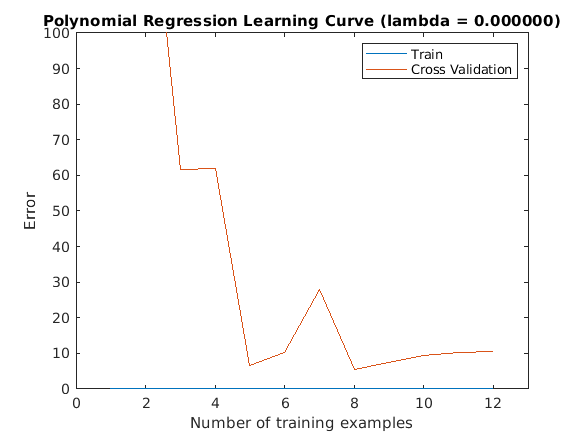

plot(1:m, error_train, 1:m, error_val);
title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

    To better understand the problems with the unregularized $\lambda=0$ model, you can see that the learning curve (Figure 5) shows the same effect where the low training error is low, but the cross validation error is high. There is a gap between the training and cross validation errors, indicating a high variance problem. One way to combat the overfitting (high-variance) problem is to add regularization to the model. In the next section, you will get to try different $\lambda$ parameters to see how regularization can lead to a better model.

### 3.2 Optional (ungraded) exercise: Adjusting the regularization parameter

In this section, you will get to observe how the regularization parameter affects the bias-variance of regularized polynomial regression. You should now modify the the `lambda` parameter in the code below and try $\lambda = 1,\; 100$. 

% Choose the value of lambda
lambda = 1;
[theta] = trainLinearReg(X_poly, y, lambda);

% Plot training data and fit
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
plotFit(min(X), max(X), mu, sigma, theta, p);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
title (sprintf('Polynomial Regression Fit (lambda = %f)', lambda));
[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);
plot(1:m, error_train, 1:m, error_val);
title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

For each of these values, the code should generate a polynomial fit to the data and also a learning curve.

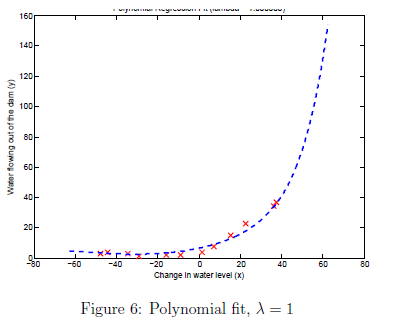

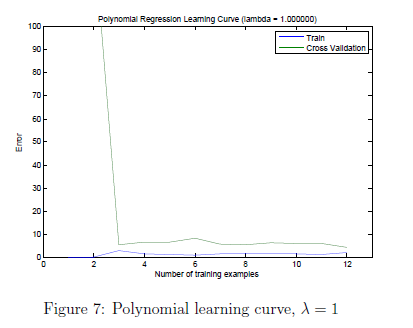

    For $\lambda= 1$, you should see a polynomial fit that follows the data trend well (Figure 6) and a learning curve (Figure 7) showing that both the cross validation and training error converge to a relatively low value. This shows the $\lambda= 1$ regularized polynomial regression model does not have the high bias or high-variance problems. In effect, it achieves a good trade-off between bias and variance.

    For $\lambda= 100$, you should see a polynomial fit (Figure 8) that does not follow the data well. In this case, there is too much regularization and the model is unable to fit the training data.

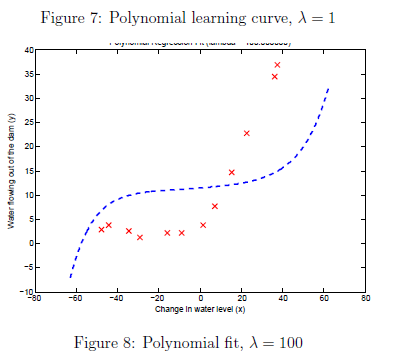

### 3.3 Selecting lambda using a cross validation set

From the previous parts of the exercise, you observed that the value of $\lambda$ can significantly affect the results of regularized polynomial regression on the training and cross validation set. In particular, a model without regularization ($\lambda = 0$) fits the training set well, but does not generalize. Conversely, a model with too much regularization ($\lambda=100$)  does not fit the training set and testing set well. A good choice of $\lambda$ (e.g. $\lambda=1$) can provide a good fit to the data.

    In this section, you will implement an automated method to select the parameter. Concretely, you will use a cross validation set to evaluate how good each $\lambda$ value is. After selecting the best $\lambda$ value using the cross validation set, we can then evaluate the model on the test set to estimate how well the model will perform on actual unseen data. Your task is to complete the code in `validationCurve.m`. Specifically, you should should use the `trainLinearReg` function to train the model using different values of $\lambda$ and compute the training error and cross validation error. The function will try $\lambda$ in the following range: {0, 0.001, 0.003, 0.01, 0.03, 0.1, 0.3, 1, 3, 10}.

    After you have completed the code, the code below will run your function and plot a cross validation curve of error v.s $\lambda$ that allows you select which $\lambda$ parameter to use. You should see a plot similar to Figure 9. 

[lambda_vec, error_train, error_val] = validationCurve(X_poly, y, X_poly_val, yval);

Iteration     1 | Cost: 2.865325e-01
Iteration     2 | Cost: 1.896079e-03
Iteration     3 | Cost: 5.614798e-08
Iteration     4 | Cost: 6.250433e-09
Iteration     5 | Cost: 1.771778e-10
Iteration     6 | Cost: 5.404078e-12
Iteration     7 | Cost: 3.142740e-13
Iteration     8 | Cost: 2.182675e-15
Iteration     9 | Cost: 2.113504e-16
Iteration    10 | Cost: 2.257216e-18
Iteration    11 | Cost: 2.888868e-19
Iteration    12 | Cost: 1.569615e-20
Iteration    13 | Cost: 1.041735e-22
Iteration    14 | Cost: 6.923008e-24
Iteration    15 | Cost: 1.416410e-26
Iteration    16 | Cost: 1.692205e-27
Iteration    17 | Cost: 7.730837e-29
Iteration    18 | Cost: 9.860761e-32
Iteration    19 | Cost: 0.000000e+00
Iteration     1 | Cost: 2.929259e-01
Iteration     2 | Cost: 1.781842e-02
Iteration     3 | Cost: 1.535899e-02
Iteration     1 | Cost: 3.057126e-01
Iteration     2 | Cost: 4.957682e-02
Iteration     3 | Cost: 4.625047e-02
Iteration     1 | Cost: 3.504661e-01
Iteration     2 | Cost: 1.598529e-01
I

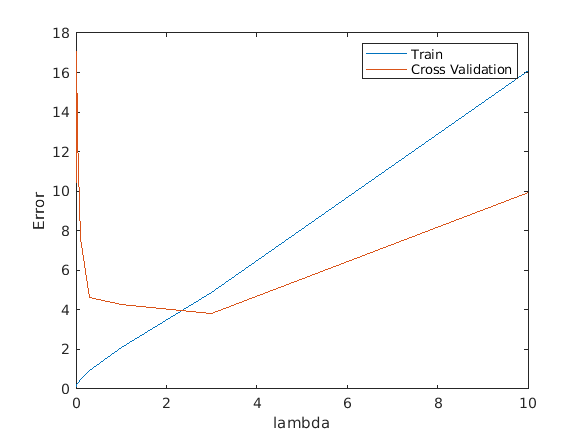

plot(lambda_vec, error_train, lambda_vec, error_val);
legend('Train', 'Cross Validation');
xlabel('lambda');
ylabel('Error');

for i = 1:length(lambda_vec)
    if i == 1
        fprintf('lambda\t\tTrain Error\tValidation Error\n');
    end
    fprintf('%f\t%f\t%f\n',lambda_vec(i), error_train(i), error_val(i));
end

lambda		Train Error	Validation Error


0.000000	0.116602	10.421926
0.001000	0.141061	14.474212
0.003000	0.177829	16.752565
0.010000	0.221255	17.041084
0.030000	0.281890	12.829419
0.100000	0.459318	7.587013
0.300000	0.921760	4.636833
1.000000	2.076188	4.260625
3.000000	4.901351	3.822907
10.000000	16.092213	9.945509


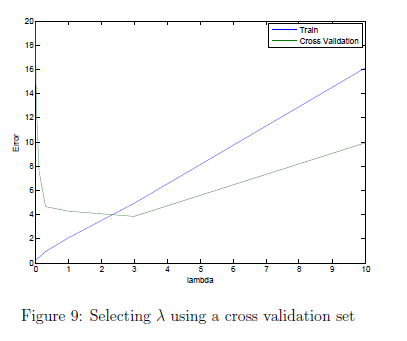

In this figure, we can see that the best value of $\lambda$ is around 3. Due to randomness in the training and validation splits of the dataset, the cross validation error can sometimes be lower than the training error. 

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 3.4 Optional (ungraded) exercise: Computing test set error

In the previous part of the exercise, you implemented code to compute the cross validation error for various values of the regularization parameter $\lambda$. However, to get a better indication of the model's performance in the real world, it is important to evaluate the 'final' model on a test set that was not used in any part of training (that is, it was neither used to select the $\lambda$ parameters, nor to learn the model parameters $\theta$).

    For this optional (ungraded) exercise, you should compute the test error using the best value of $\lambda$ you found. In our cross validation, we obtained a test error of 3.8599 for $\lambda= 3.$ You do not need to submit any solutions for this optional (ungraded) exercise.

%%%%%%%%% Add your code to compute the test error below %%%%%%%%%%%



### 3.5 Optional (ungraded) exercise: Plotting learning curves with randomly selected examples

In practice, especially for small training sets, when you plot learning curves to debug your algorithms, it is often helpful to average across multiple sets of randomly selected examples to determine the training error and cross validation error. Concretely, to determine the training error and cross validation error for $i$ examples, you should first randomly select $i$ examples from the training set and $i$ examples from the cross validation set. You will then learn the parameters $\theta$ using the randomly chosen training set and evaluate the parameters $\theta$ on the randomly chosen training set and cross validation set. The above steps should then be repeated multiple times (say 50) and the averaged error should be used to determine the training error and cross validation error for $i$ examples.

     For this optional (ungraded) exercise, you should implement the above strategy for computing the learning curves in `learningCurve.m` and use the code below to call your modified function and generate the plot.

lambda = 0.01;
[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);
plot(1:m, error_train, 1:m, error_val);

title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

For reference, Figure 10 shows the learning curve we obtained for polynomial regression with $\lambda= 0.01$. 

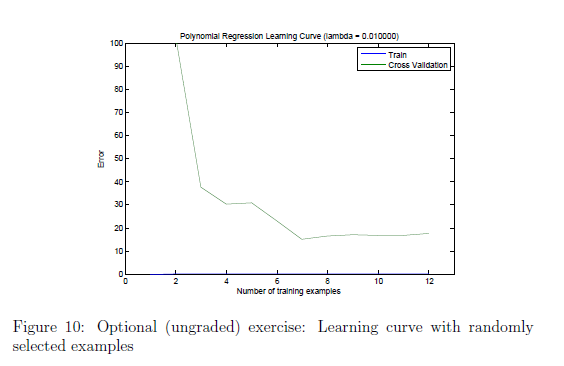

Your figure may differ slightly due to the random selection of examples. 

*You do not need to submit any solutions for this optional (ungraded) exercise.*

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

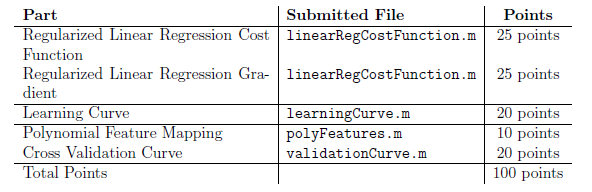

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.